clear
clc
close all

nchan = 16; % number of channels
fs = 25000; % sampling rate [kHz]

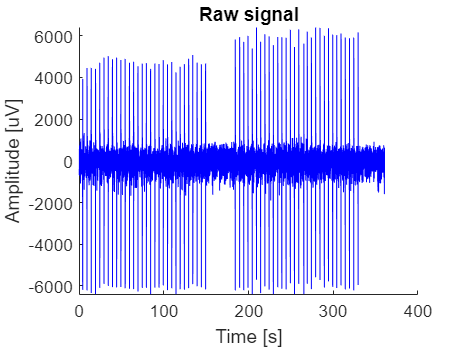

load(fullfile("SHAM/R21-21",'PreLesion_Mapping','Raw_P1_Ch_000.mat'));

t=(1:length(data))/fs; 
plot(t,data,Color='b')  
box off
title('Raw signal')
xlabel('Time [s]')
ylabel('Amplitude [uV]')

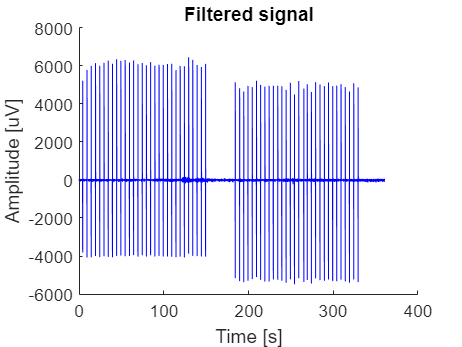

Wn_norm = [300 3000]/(fs/2); 
[b,a] = butter(2, Wn_norm, 'bandpass');
sham_filtered =  filtfilt(b,a,double(data));


% plot(t,data) 
% hold on
plot(t,sham_filtered,Color='b')
% hold off
box off
title('Filtered signal')
xlabel('Time [s]')
ylabel('Amplitude [uV]')

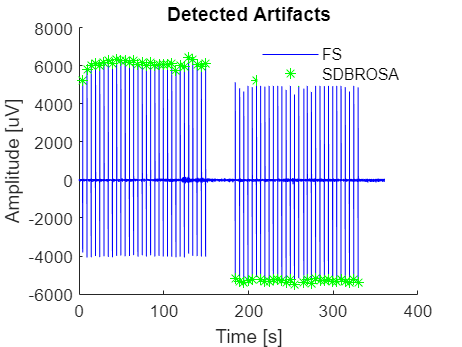

[~, artifact_train] = findpeaks(abs(sham_filtered), 'MinPeakHeight',2000, 'MinPeakDistance',4*fs);

plot(t,sham_filtered,Color='b')
hold on
plot(t(artifact_train),sham_filtered(artifact_train),'*',Color=[0 1 0])
hold off
box off
title('Detected Artifacts')
xlabel('Time [s]')
ylabel('Amplitude [uV]')
legend('FS','SDBROSA')
legend box off

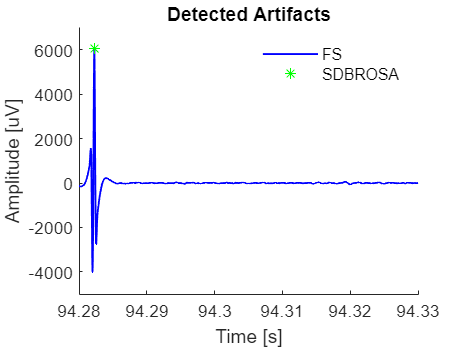

window_to_see=0.015; % 15ms
campioni_da_vedere=window_to_see*fs;

plot(t,sham_filtered,'LineWidth',1,Color='b')
hold on
plot(t(artifact_train),sham_filtered(artifact_train),'*',Color=[0 1 0])
hold off
ylim([-5000 7000])
xlim([94.28 94.33])
box off
title('Detected Artifacts')
xlabel('Time [s]')
ylabel('Amplitude [uV]')
legend('FS','SDBROSA')
legend box off

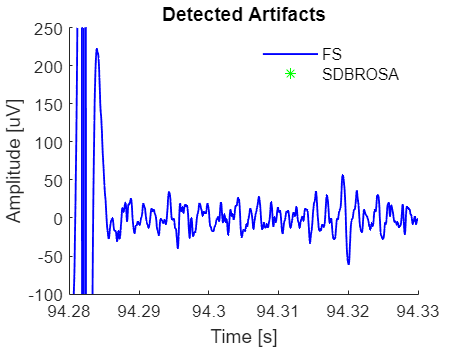


plot(t,sham_filtered,'LineWidth',1,Color='b')
hold on
plot(t(artifact_train),sham_filtered(artifact_train),'*',Color=[0 1 0])
hold off
ylim([-100 250])
xlim([94.28 94.33])
box off
title('Detected Artifacts')
xlabel('Time [s]')
ylabel('Amplitude [uV]')
legend('FS','SDBROSA')
legend box off


% plot(t(artifact_train(19):artifact_train(19)+campioni_da_vedere),sham_filtered(artifact_train(19):artifact_train(19)+campioni_da_vedere))
% hold on
% plot(t(artifact_train(19)),sham_filtered(artifact_train(19)),'*',Color=[0 1 0])
% hold off
% ylim([-60 60])
% xlim([94.28 94.33])
% box off
% title('Detected Artifacts')
% xlabel('Time [s]')
% ylabel('Amplitude [uV]')

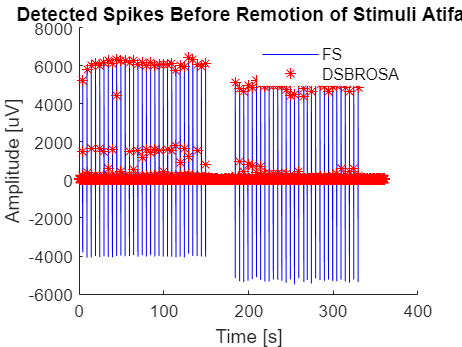

th = 6.5 * std(sham_filtered(1:2.5*fs)); %% ---> PSTH quasi accettabile. --> è 7, ma puo andare da 5 a 8
% th = 5.6 * mad(sham_filtered(1:2.5*fs)); 
% th = 4.15 * mad(sham_filtered); 
% th = 0.85 * std(sham_filtered); 
% th = 36; 

time_wdw = 0.002; % 2-3 ms ---> variare questo
% window = 45; %% ---> cambiare questo
window = time_wdw*fs;
spike_dif = differential_th(sham_filtered, window, th);

% PLP = 0.002 *fs; % ---> PLP = 3; % samples - peak lifetime period
% overshot = 0.001*fs; % ---> overshot = 3;
% RP = 0.002 * fs % ---> RP = 4; % samples - refractory period (2-3 ms)
% spike_dif = PTSD(sham_filtered, PLP, overshot, th, RP);

spike_pos = spike_dif(:,2);
spike_train = zeros(1,size(sham_filtered,2));

%create spike train
for j = 1:size(spike_pos,1)
    spike_train(spike_pos(j)) = 1;
end

%plot(t,sham_pre,Color='b')
plot(t,sham_filtered,Color='b')
hold on
%plot(t(artifact_train),sham_pre(artifact_train),'*',Color=[0 1 0])
%plot(t(artifact_train),sham_filtered(artifact_train),'o',Color=[0 1 0])
plot(t(spike_pos),sham_filtered(spike_pos),'*',Color='r')
hold off
box off
title('Detected Spikes Before Remotion of Stimuli Atifact')
xlabel('Time [s]')
ylabel('Amplitude [uV]')
legend('FS','DSBROSA')
legend box off

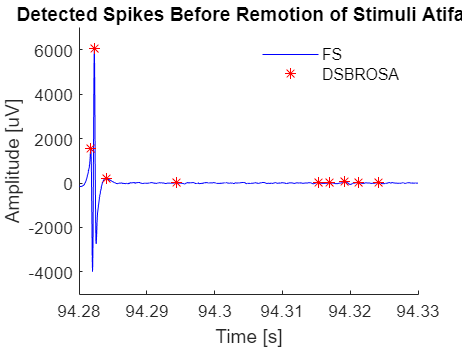


%plot(t,sham_pre,Color='b')
plot(t,sham_filtered,Color='b')
hold on
%plot(t(artifact_train),sham_pre(artifact_train),'*',Color=[0 1 0])
%plot(t(artifact_train),sham_filtered(artifact_train),'o',Color=[0 1 0])
plot(t(spike_pos),sham_filtered(spike_pos),'*',Color='r')
hold off
box off
ylim([-5000 7000])
xlim([94.28 94.33])
title('Detected Spikes Before Remotion of Stimuli Atifact')
xlabel('Time [s]')
ylabel('Amplitude [uV]')
legend('FS','DSBROSA')
legend box off

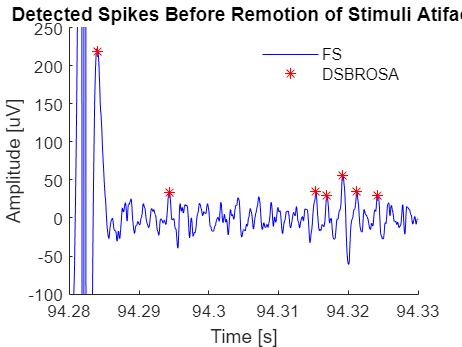


%plot(t,sham_pre,Color='b')
plot(t,sham_filtered,Color='b')
hold on
%plot(t(artifact_train),sham_pre(artifact_train),'*',Color=[0 1 0])
%plot(t(artifact_train),sham_filtered(artifact_train),'o',Color=[0 1 0])
plot(t(spike_pos),sham_filtered(spike_pos),'*',Color='r')
hold off
box off
ylim([-100 250])
xlim([94.28 94.33])
title('Detected Spikes Before Remotion of Stimuli Atifact')
xlabel('Time [s]')
ylabel('Amplitude [uV]')
legend('FS','DSBROSA')
legend box off

window_to_remove=0.005; % 5 ms
campioni_da_togliere=window_to_remove*fs;

% k=4;
% plot(t(artifact_train(k)+1:artifact_train(k)+campioni_da_togliere),sham_filtered(artifact_train(k)+1:artifact_train(k)+campioni_da_togliere),LineWidth=5)
% hold on
% plot(t,sham_filtered)
% hold off

sham_pre=sham_filtered;
% sham_filtered=sham_filtered;
for i=1:length(artifact_train)
    indice_inizio=artifact_train(i)+0;%%-->non so se partire da 0 o da 1--> si dovrebbe partire da 0
    indice_fine=artifact_train(i)+campioni_da_togliere-1;%--> non so se togliere 1 o 0
    sham_filtered(indice_inizio:indice_fine)=zeros(1,campioni_da_togliere);
end

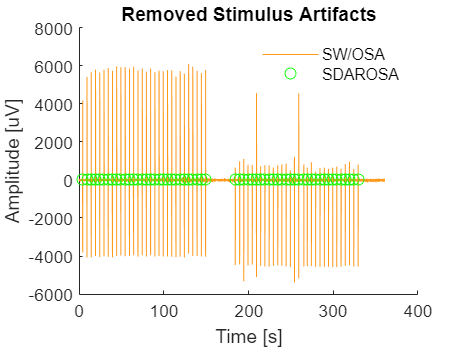

% plot(t,sham_pre,Color='b')
plot(t,sham_filtered,Color=[1 0.6 0.1])
hold on
% plot(t(artifact_train),sham_pre(artifact_train),'*',Color=[0 1 0])
plot(t(artifact_train),sham_filtered(artifact_train),'o',Color=[0 1 0])
hold off
box off
title('Removed Stimulus Artifacts')
xlabel('Time [s]')
ylabel('Amplitude [uV]')
legend('SW/OSA','SDAROSA')
legend box off

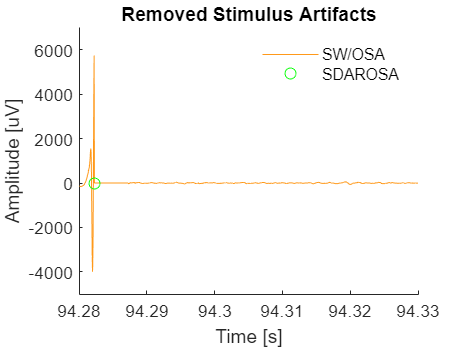


% plot(t,sham_pre,Color='b')
plot(t,sham_filtered,Color=[1 0.6 0.1])
hold on
% plot(t(artifact_train),sham_pre(artifact_train),'*',Color=[0 1 0])
plot(t(artifact_train),sham_filtered(artifact_train),'o',Color=[0 1 0])
hold off
box off
ylim([-5000 7000])
xlim([94.28 94.33])
title('Removed Stimulus Artifacts')
xlabel('Time [s]')
ylabel('Amplitude [uV]')
legend('SW/OSA','SDAROSA')
legend box off

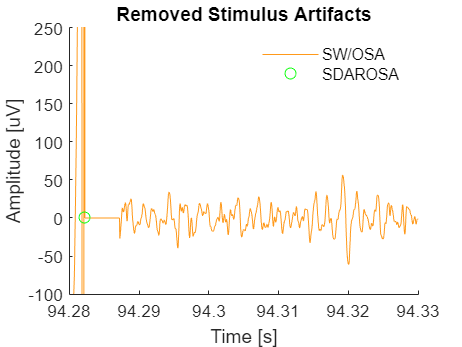


% plot(t,sham_pre,Color='b')
plot(t,sham_filtered,Color=[1 0.6 0.1])
hold on
% plot(t(artifact_train),sham_pre(artifact_train),'*',Color=[0 1 0])
plot(t(artifact_train),sham_filtered(artifact_train),'o',Color=[0 1 0])
hold off
box off
ylim([-100 250])
xlim([94.28 94.33])
title('Removed Stimulus Artifacts')
xlabel('Time [s]')
ylabel('Amplitude [uV]')
legend('SW/OSA','SDAROSA')
legend box off

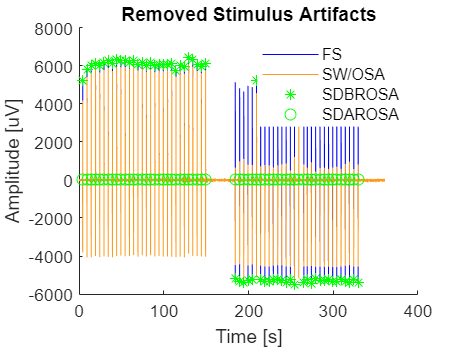

plot(t,sham_pre,Color='b')
hold on

plot(t,sham_filtered,Color=[1 0.6 0.1])
plot(t(artifact_train),sham_pre(artifact_train),'*',Color=[0 1 0])
plot(t(artifact_train),sham_filtered(artifact_train),'o',Color=[0 1 0])
hold off
box off
title('Removed Stimulus Artifacts')
xlabel('Time [s]')
ylabel('Amplitude [uV]')
legend('FS','SW/OSA','SDBROSA','SDAROSA')

legend box off

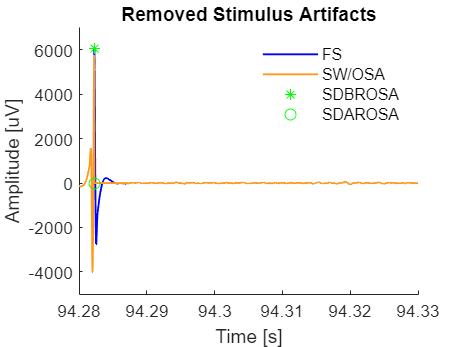

plot(t,sham_pre,'LineWidth',1,Color='b')
hold on

plot(t,sham_filtered,'LineWidth',1,Color=[1 0.6 0.1])
plot(t(artifact_train),sham_pre(artifact_train),'*',Color=[0 1 0])
plot(t(artifact_train),sham_filtered(artifact_train),'o',Color=[0 1 0])
hold off
box off
ylim([-5000 7000])
xlim([94.28 94.33])
title('Removed Stimulus Artifacts')
xlabel('Time [s]')
ylabel('Amplitude [uV]')
legend('FS','SW/OSA','SDBROSA','SDAROSA')
legend box off

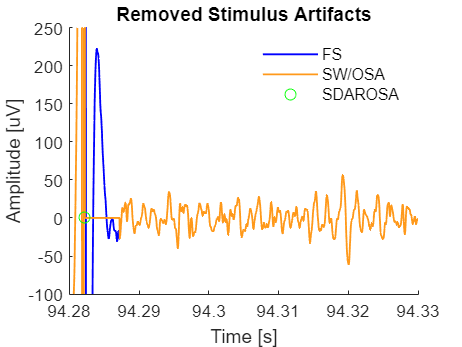

plot(t,sham_pre,'LineWidth',1,Color='b')
hold on

plot(t,sham_filtered,'LineWidth',1,Color=[1 0.6 0.1])
plot(t(artifact_train),sham_pre(artifact_train),'*',Color=[0 1 0])
plot(t(artifact_train),sham_filtered(artifact_train),'o',Color=[0 1 0])
hold off
box off
ylim([-100 250])
xlim([94.28 94.33])
title('Removed Stimulus Artifacts')
xlabel('Time [s]')
ylabel('Amplitude [uV]')
legend('FS','SW/OSA','','SDAROSA')
legend box off


% plot(t(artifact_train(19):artifact_train(19)+campioni_da_vedere),sham_pre(artifact_train(19):artifact_train(19)+campioni_da_vedere),'LineWidth',2)
% hold on
% plot(t(artifact_train(19)),sham_pre(artifact_train(19)),'*',Color=[0 1 0])
% plot(t(artifact_train(19):artifact_train(19)+campioni_da_vedere),sham_filtered(artifact_train(19):artifact_train(19)+campioni_da_vedere),'LineWidth',2)
% plot(t(artifact_train(19)),sham_filtered(artifact_train(19)),'o',Color=[0 1 0])
% hold off
% box off
% ylim([-5000 7000])
% xlim([94.28 94.33])
% title('Removed Stimulus Artifacts')
% xlabel('Time [s]')
% ylabel('Amplitude [uV]')
% legend('filtered signal','','stim artifact removed')
% legend box off

% k=4;
% figure
% plot(t(artifact_train(k)+1:artifact_train(k)+campioni_da_togliere),sham_filtered(artifact_train(k)+1:artifact_train(k)+campioni_da_togliere),LineWidth=5)
% hold on
% plot(t(artifact_train(k)+1:artifact_train(k)+campioni_da_togliere),sham_filtered(artifact_train(k)+1:artifact_train(k)+campioni_da_togliere),LineWidth=5)
% % plot(t(artifact_train(k):artifact_train(k+1)),sham_filtered(artifact_train(k):artifact_train(k+1)))
% plot(t(artifact_train(k):artifact_train(k+1)),sham_filtered(artifact_train(k):artifact_train(k+1)))
% hold off

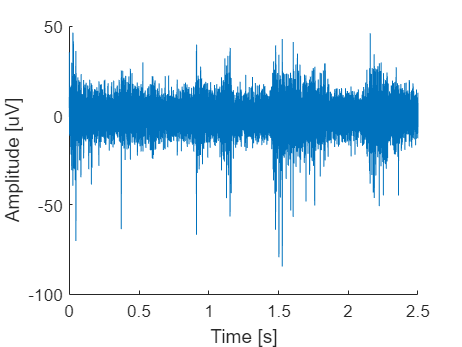

t_parziale=(1:length(data(1:2.5*fs)))/fs; 
plot(t_parziale,sham_filtered(1:2.5*fs))
box off
xlabel('Time [s]')
ylabel('Amplitude [uV]')

th = 6.5 * std(sham_filtered(1:2.5*fs)); %% ---> PSTH quasi accettabile. --> è 7, ma puo andare da 5 a 8
% th = 5.6 * mad(sham_filtered(1:2.5*fs)); 
% th = 4.15 * mad(sham_filtered); 
% th = 0.85 * std(sham_filtered); 
% th = 36; 

time_wdw = 0.002; % 2-3 ms ---> variare questo
% window = 45; %% ---> cambiare questo
window = time_wdw*fs;
spike_dif = differential_th(sham_filtered, window, th);

% PLP = 0.002 *fs; % ---> PLP = 3; % samples - peak lifetime period
% overshot = 0.001*fs; % ---> overshot = 3;
% RP = 0.002 * fs % ---> RP = 4; % samples - refractory period (2-3 ms)
% spike_dif = PTSD(sham_filtered, PLP, overshot, th, RP);

spike_pos = spike_dif(:,2);
spike_train = zeros(1,size(sham_filtered,2));

%create spike train
for j = 1:size(spike_pos,1)
    spike_train(spike_pos(j)) = 1;
end

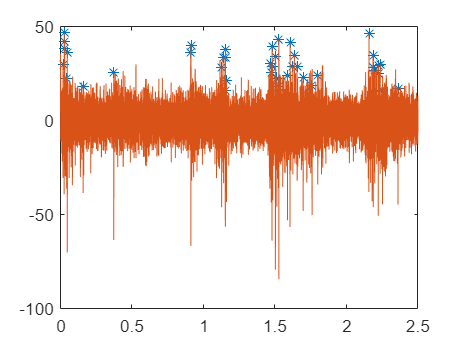

pos_parziale=find(spike_pos<(2.5*fs));
plot(t_parziale(spike_pos(pos_parziale)),sham_filtered(spike_pos(pos_parziale)),'*')
hold on
plot(t_parziale,sham_filtered(1:2.5*fs))
hold off

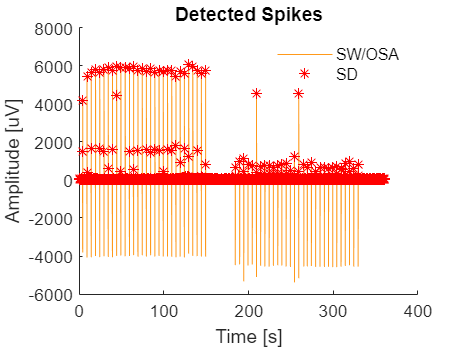

%plot(t,sham_pre,Color='b')
plot(t,sham_filtered,Color=[1 0.6 0.1])
hold on
%plot(t(artifact_train),sham_pre(artifact_train),'*',Color=[0 1 0])
%plot(t(artifact_train),sham_filtered(artifact_train),'o',Color=[0 1 0])
plot(t(spike_pos),sham_filtered(spike_pos),'*',Color='r')
hold off
box off
title('Detected Spikes')
xlabel('Time [s]')
ylabel('Amplitude [uV]')
legend('SW/OSA','SD')
legend box off

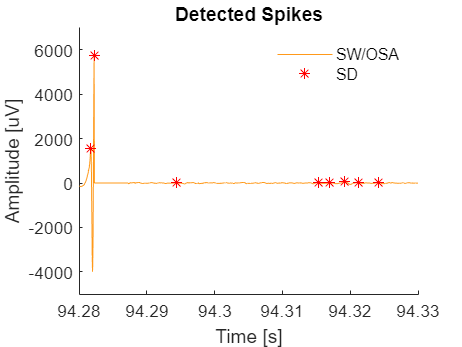


%plot(t,sham_pre,Color='b')
plot(t,sham_filtered,Color=[1 0.6 0.1])
hold on
%plot(t(artifact_train),sham_pre(artifact_train),'*',Color=[0 1 0])
%plot(t(artifact_train),sham_filtered(artifact_train),'o',Color=[0 1 0])
plot(t(spike_pos),sham_filtered(spike_pos),'*',Color='r')
hold off
box off
ylim([-5000 7000])
xlim([94.28 94.33])
title('Detected Spikes')
xlabel('Time [s]')
ylabel('Amplitude [uV]')
legend('SW/OSA','SD')
legend box off

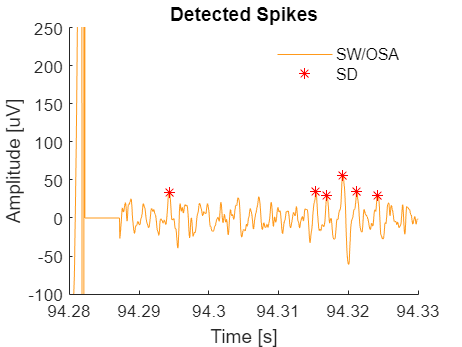


%plot(t,sham_pre,Color='b')
plot(t,sham_filtered,Color=[1 0.6 0.1])
hold on
%plot(t(artifact_train),sham_pre(artifact_train),'*',Color=[0 1 0])
%plot(t(artifact_train),sham_filtered(artifact_train),'o',Color=[0 1 0])
plot(t(spike_pos),sham_filtered(spike_pos),'*',Color='r')
hold off
box off
ylim([-100 250])
xlim([94.28 94.33])
title('Detected Spikes')
xlabel('Time [s]')
ylabel('Amplitude [uV]')
legend('SW/OSA','SD')
legend box off

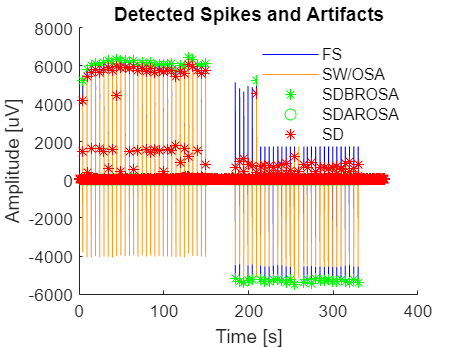

plot(t,sham_pre,Color='b')
hold on
plot(t,sham_filtered,Color=[1 0.6 0.1])
plot(t(artifact_train),sham_pre(artifact_train),'*',Color=[0 1 0])
plot(t(artifact_train),sham_filtered(artifact_train),'o',Color=[0 1 0])
plot(t(spike_pos),sham_filtered(spike_pos),'*',Color='r')
hold off
box off
title('Detected Spikes and Artifacts')
xlabel('Time [s]')
ylabel('Amplitude [uV]')
legend('FS','SW/OSA','SDBROSA','SDAROSA','SD')
legend box off

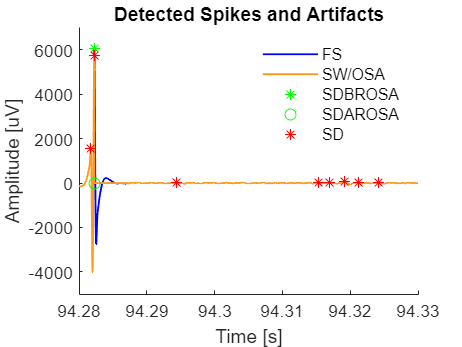


plot(t,sham_pre,'LineWidth',1,Color='b')
hold on
plot(t,sham_filtered,'LineWidth',1,Color=[1 0.6 0.1])
plot(t(artifact_train),sham_pre(artifact_train),'*',Color=[0 1 0])
plot(t(artifact_train),sham_filtered(artifact_train),'o',Color=[0 1 0])
plot(t(spike_pos),sham_filtered(spike_pos),'*',Color='r')
hold off
ylim([-5000 7000])
xlim([94.28 94.33])
box off
title('Detected Spikes and Artifacts')
xlabel('Time [s]')
ylabel('Amplitude [uV]')
legend('FS','SW/OSA','SDBROSA','SDAROSA','SD')
legend box off

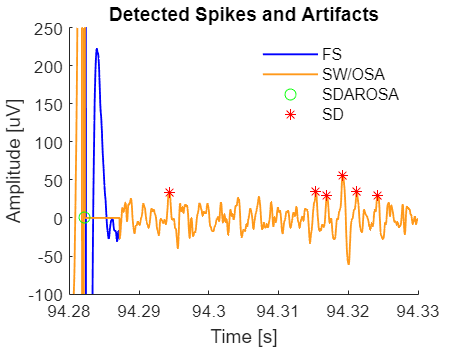


plot(t,sham_pre,'LineWidth',1,Color='b')
hold on
plot(t,sham_filtered,'LineWidth',1,Color=[1 0.6 0.1])
plot(t(artifact_train),sham_pre(artifact_train),'*',Color=[0 1 0])
plot(t(artifact_train),sham_filtered(artifact_train),'o',Color=[0 1 0])
plot(t(spike_pos),sham_filtered(spike_pos),'*',Color='r')
hold off
ylim([-100 250])
xlim([94.28 94.33])
box off
title('Detected Spikes and Artifacts')
xlabel('Time [s]')
ylabel('Amplitude [uV]')
legend('FS','SW/OSA','','SDAROSA','SD')
legend box off

% pos_spike_parziale=find(spike_pos>artifact_train(19)&spike_pos<artifact_train(19)+campioni_da_vedere);
% % plot(t_parziale(spike_pos(pos_spike_parziale)),sham_filtered(spike_pos(pos_spike_parziale)),'*')
% 
% plot(t(artifact_train(19):artifact_train(19)+campioni_da_vedere),sham_pre(artifact_train(19):artifact_train(19)+campioni_da_vedere),'LineWidth',2)
% hold on
% plot(t(spike_pos(pos_spike_parziale)),sham_filtered(spike_pos(pos_spike_parziale)),'*')
% plot(t(artifact_train(19):artifact_train(19)+campioni_da_vedere),sham_filtered(artifact_train(19):artifact_train(19)+campioni_da_vedere),'LineWidth',2)
% plot(t(artifact_train(19)),sham_filtered(artifact_train(19)),'o',Color=[0 1 0])
% plot(t(artifact_train(19)),sham_pre(artifact_train(19)),'*',Color=[0 1 0])
% hold off
% box off
% title('Removed Stimulus Artifacts')
% xlabel('Time [s]')
% ylabel('Amplitude [uV]')
% legend('','filtered signal','stim artifact removed')
% legend box off

% plot(t(artifact_train(19):artifact_train(19)+campioni_da_vedere),sham_pre(artifact_train(19):artifact_train(19)+campioni_da_vedere))
% hold on
% plot(t(spike_pos(pos_spike_parziale)),sham_filtered(spike_pos(pos_spike_parziale)),'*')
% plot(t(artifact_train(19):artifact_train(19)+campioni_da_vedere),sham_filtered(artifact_train(19):artifact_train(19)+campioni_da_vedere))
% plot(t(artifact_train(19)),sham_filtered(artifact_train(19)),'o',Color=[0 1 0])
% plot(t(artifact_train(19)),sham_pre(artifact_train(19)),'*',Color=[0 1 0])
% hold off
% box off
% ylim([-60 60])
% xlim([94.28 94.33])
% title('Removed Stimulus Artifacts')
% xlabel('Time [s]')
% ylabel('Amplitude [uV]')
% legend('','filtered signal','stim artifact removed')
% legend box off

%PSTH
wdwsize = 0.4; % sec - wdw after stimulus
wdwsize_samples = wdwsize*fs;

binsize = 0.004; % sec
binsize_samples = binsize*fs;

psth_ch = my_psth(spike_train, artifact_train ,wdwsize_samples,binsize_samples);
inter = psth_ch/(length(artifact_train));
PSTH = inter/binsize;

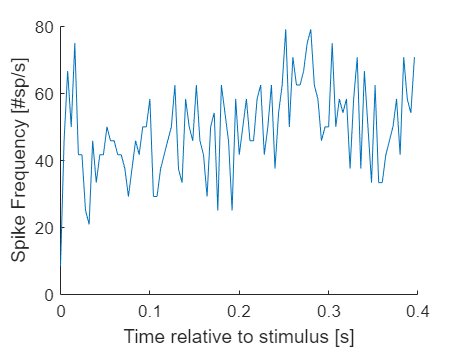

time = 0:binsize:wdwsize-binsize;
% time = 0:binsize:wdwsize;

figure()
plot(time,PSTH)
% plot(time,[0,PSTH])
box off
xlabel('Time relative to stimulus [s]')
ylabel('Spike Frequency [#sp/s]')
xticks(0:0.1:wdwsize)
xlim([0 wdwsize])

%title('CHANNEL1')

function spike_train = differential_th(data, wdw_length, th)

T = length(data);
num_wdw = T/wdw_length;
num_wdw = floor(num_wdw);

xStart = 1:wdw_length:length(data)-1;
xEnd = xStart + wdw_length -1;

spike = zeros(num_wdw,2);

for iwdw = 1:num_wdw

    data_wdw = data(1,xStart(iwdw):xEnd(iwdw));

    [ampl_min, ~] = min(data_wdw);
    [ampl_max, pos_max] = max(data_wdw);

    if (ampl_max- ampl_min) > th % Check if the difference between max and min values is higher than threshold
        pos = xStart(iwdw):xEnd(iwdw);
        spike(iwdw,:) = [ampl_max, pos(pos_max)];
    end

end

spike_train = spike(spike(:,2)~=0,:); % Delete all false positive

end

function psth_output = my_psth(spike_train, artifact_train,wdw,bin)

nbins = wdw/bin; %num of  bins

psth_output= zeros(1,nbins);
for istim=1:length(artifact_train)
    for j=1:nbins
        k = find(spike_train((artifact_train(istim)+(j-1)*bin):(artifact_train(istim)+j*bin))); %search in each bin %%--->aggiunte parentesi
        psth_output(j) = psth_output(j) + length(k);
    end
end

end

function spike_train = PTSD(data, PLP, overshot, th, RP)

RM = find(islocalmax(data)==1); % relative maximum

j = 1;
for imax = 1:length(RM)

    pos_max = RM(imax);

    ampl_max = data(pos_max);

    if pos_max+PLP < length(data)

        rm = islocalmin(data(imax:imax+PLP)); % relative minimum within PLP

        pos = pos_max:pos_max+PLP;

        ampl_min = data(pos(rm));

        if (sum(rm) == 0) % if we do not found a local minimum
            rm = islocalmin(data(imax:imax+PLP+overshot)); % Add overshot
            pos = pos_max:pos_max+PLP+overshot;
            ampl_min = data(pos(rm));
        end

        if (abs(ampl_max - ampl_min) >= th) % Check differential threshold
            if j == 1
                spike_train(j,:) = [ampl_max, pos_max];
                j = j+1;
            else
                if (abs(spike_train(j-1,2) - imax) > RP) % Check refractory period
                    spike_train(j,:) = [ampl_max, pos_max];
                    j = j+1;
                end
            end

        end
    end
end
end
